# はじめに

人手不足の昨今、『業務負荷の見える化』を求められてはいませんか。

だのに職場が古風で、プロジェクト管理ツールなど導入されてはいない。

あるいは導入されたプロジェクト管理ツールがイケてなくて、ぜんぜん定着していない。

そんな時、あなたならどうしますか？

私「うーん、予定はOutlookで管理してるから、そのデータを負荷の見える化にも使えないものか…」

私「…せや！MATLABで解決したらええんや！」

私「テキストディープラーニング使えば何か出来るやろ、[Advent Calendar](https://qiita.com/aoimidori/items/796db2e0ce90f64f30d1)にそういうのあったし。」

ということで、MATLABで解決していきます。

まず本稿では、Outlookから予定表をぶっこ抜くMATLABに持ってくるまでを示します。

なお、コードの大半は下記URLを参考に作成しています。

そのままだと動かなかったのでメンテしたり加筆したりしました。

[https://stackoverflow.com/questions/40429116/retrieving-outlook-calendar-items-using-matlab](https://stackoverflow.com/questions/40429116/retrieving-outlook-calendar-items-using-matlab)

clear all;
close all;

## 1. Outlook APIに接続

下記コマンドを実行することで、MATLABからOutlook APIに接続します。

outlook = actxserver('Outlook.Application');
mapi = outlook.GetNamespace('mapi');

次に、GetDefaultFolderkメソッドを叩いてOutlookの所定のフォルダにアクセスします。

メソッドの引数とフォルダの対応表は下記URLを参考、予定表フォルダは「9」にあります。

[Baccho Log [WSH]Outlookの操作](https://baccholog.com/archives/128)

explorer = mapi.GetDefaultFolder(9).GetExplorer;

さらに掘り下げていくことで、個人用や共用の予定表を取得することが出来ます。

今回は個人用の予定表を取得してみましょう。

NavModule = explorer.NavigationPane.Modules.GetNavigationModule(1); %予定表を取得
NavGroup = NavModule.NavigationGroups.GetDefaultNavigationGroup(1);% 個人用の予定表を取得
%NavGroup = NavModule.NavigationGroups.GetDefaultNavigationGroup(2);% 共用の予定表を取得

## 2.特定の日時でフィルタする

『yyyy/MM/dd HH:mm』または『MM/dd/yyyy HH:mm』のフォーマットで日付を指定します。HH:mmは省略可能です。

予定を日時でフィルタする場合、予定の開始時間あるいは終了時間でフィルタすることが可能です。開始時間でフィルタする場合は下記のようにします。

StartDate_MIN = '2020/02/05';
StartDate_MAX = '2020/02/06';

%[Start]は開始時間、[End]は終了時間をフィルタ条件として使用
filter = {['[Start] >= ''',StartDate_MIN,''' AND [Start] <= ''', StartDate_MAX, '''']};

## 3.予定を取得、MATLABのテーブルに成型する

取得の対象となるOutlook予定表は下記です。

フィルタ条件を2/5~2/6に指定したので、「家族と朝ごはん」以降の予定が取れれば成功です。

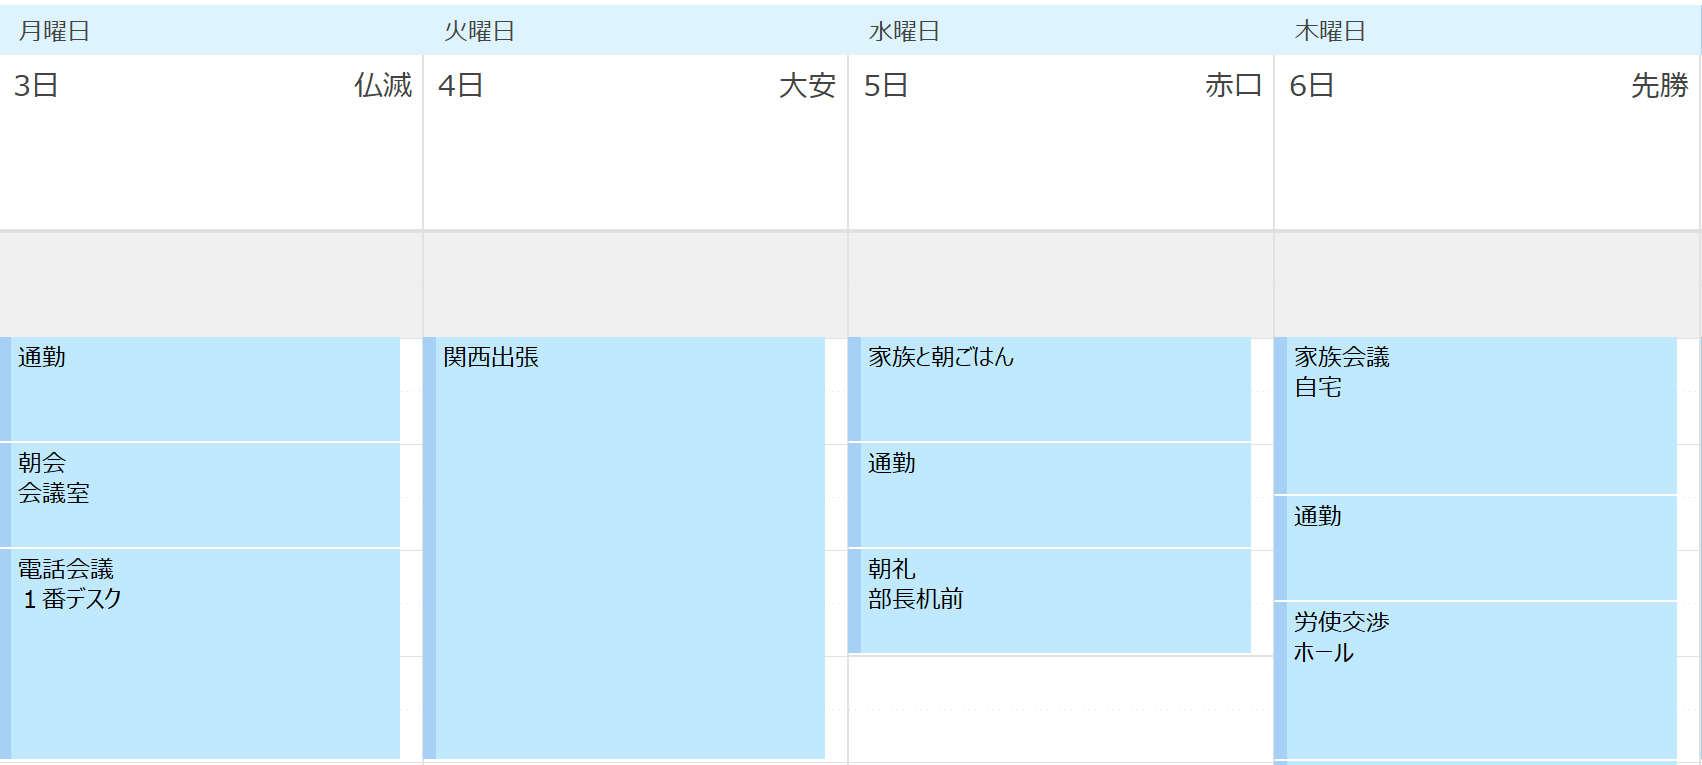

取得およびテーブルの成型は下記。

テーブル成型は色々なやり方があるとは思いますが、

for i=1:NavGroup.NavigationFolders.Count
    NavFolder = NavGroup.NavigationFolders.Item(i);
    LST = NavFolder.Folder.Items;
    %LST.IncludeRecurrences = -1;
    LST.Sort('[Start]');
    LST_Restrict = LST.Restrict(filter{1});
    Cnt = LST_Restrict.Count;
    sz = [Cnt 3];
    varNames = {'Subject','Start','End'};
    varTypes = {'string','datetime','datetime'};
    Calendar_Table = table('Size',sz,'VariableTypes',varTypes,'VariableNames',varNames);
    for j = 1:Cnt
        Calendar_Table.Subject(j) = LST_Restrict.Item(j).Subject;
        Calendar_Table.Start(j) = LST_Restrict.Item(j).Start;
        Calendar_Table.End(j) = LST_Restrict.Item(j).End;
    end
end

Calendar_Table

Calendar_Table = 3×3 table
      Subject              Start                   End        
    ____________    ___________________    ___________________

    "テスト会議"     2020/02/06 08:00:00    2020/02/06 08:30:00
    "テスト会議２"    2020/02/06 12:00:00    2020/02/06 12:30:00
    "テスト予定"     2020/02/07 08:00:00    2020/02/07 10:00:00


## 時間の長さを計算する

Calendar_Table.Dulation = Calendar_Table.End - Calendar_Table.Start

Calendar_Table = 3×4 table
      Subject              Start                   End            Dulation
    ____________    ___________________    ___________________    ________

    "テスト会議"     2020/02/06 08:00:00    2020/02/06 08:30:00    00:30:00
    "テスト会議２"    2020/02/06 12:00:00    2020/02/06 12:30:00    00:30:00
    "テスト予定"     2020/02/07 08:00:00    2020/02/07 10:00:00    02:00:00
